fname = 'double_run_1.bag';
% Create a bag file object with the file name by omitting the
% semicolon this displays some information about the bag file
bag = rosbag(fname);
  
% Display a list of the topics and message types in the bag file
bag.AvailableTopics;
 
%% Create a time series of the Odometry data
% Retrieve the messages as a cell array
geom_msgs = select(bag,'Topic','/rabbit');
 
% Create a timeseries object of the subset of message fields we are interested in
geom_ts = timeseries(geom_msgs,'Point.X','Point.Y');

% Retrieve the messages as a cell array
odom_msgs = select(bag,'Topic','/cora1/cora/sensors/p3d');
 
% Create a timeseries object of the subset of message fields we are interested in
odom_ts = timeseries(odom_msgs,'Pose.Pose.Position.X','Pose.Pose.Position.Y');

% Retrieve the messages as a cell array
odom2_msgs = select(bag,'Topic','/cora2/cora/sensors/p3d');
 
% Create a timeseries object of the subset of message fields we are interested in
odom2_ts = timeseries(odom_msgs,'Pose.Pose.Position.X','Pose.Pose.Position.Y');

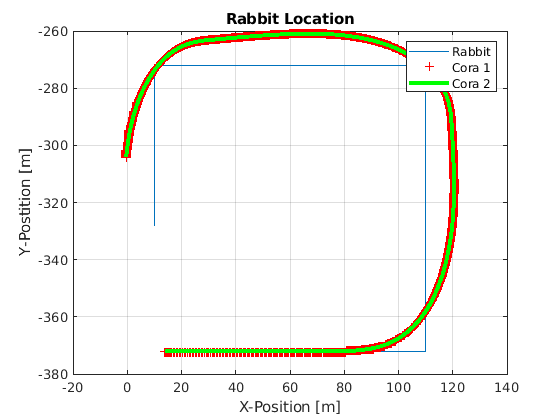

%% Plot X/Y Positions
figure(1); clf();
% Plot the Data index
plot(geom_ts.Data(:,1),geom_ts.Data(:,2))
hold on
plot(odom_ts.Data(:,1),odom_ts.Data(:,2),'+r')
plot(odom2_ts.Data(:,1),odom2_ts.Data(:,2),'g','LineWidth',3)
xlabel('X-Position [m]')
ylabel('Y-Postition [m]')
legend('Rabbit','Cora 1','Cora 2')
grid on
title('Rabbit Location')

% xlim([0 60])
% ylim([-380 -330])

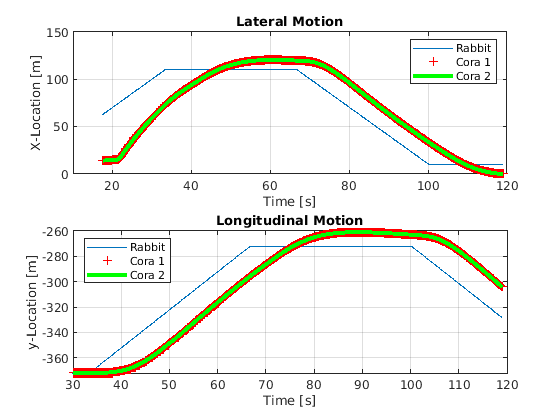

% plot x/y vs time 
figure (2); clf()
subplot(2,1,1)
plot(geom_ts.Time(:),geom_ts.Data(:,1))
hold on
plot(odom_ts.Time(:),odom_ts.Data(:,1),'+r')
plot(odom2_ts.Time(:),odom2_ts.Data(:,1),'g','LineWidth',3)
hold off
grid on
title('Lateral Motion')
xlabel('Time [s]')
ylabel('X-Location [m]')
xlim([10 120])
legend('Rabbit','Cora 1','Cora 2',"Location","northeast")

subplot(2,1,2)
plot(geom_ts.Time(:),geom_ts.Data(:,2))
hold on
plot(odom_ts.Time(:),odom_ts.Data(:,2),'+r')
plot(odom2_ts.Time(:),odom2_ts.Data(:,2),'g','LineWidth',3)
grid on
title('Longitudinal Motion')
xlabel('Time [s]')
ylabel('y-Location [m]')
xlim([30 120])
legend('Rabbit','Cora 1','Cora 2',"Location","northwest")